clc, clear
t = [0, 1, 2, 2.5, 3, 3.5, 4, 4.5, 5, 5.5, 6, 7, 8];
x = [0, 4.1, 14.9, 25.4, 37.5, 48.4, 59, 69.6, 80.3, 92.2, 103.5, 115.3, 119.8];
y = [31.6, 22.3, 7.1, 2, 3.54, 7.6, 10, 8.2, 4.3, 1.8, 5.7, 21.2, 31.1];

% syms x x1 x2 x3 x4
% eq = (x-x2)*(x-x3)*(x-x4)
% eq = expand(eq)
% d = diff(eq)
% dd = diff(d)

[xd, xdd] = PySDerDes(t, x);
[yd, ydd] = PySDerDes(t, y);
v = sqrt(xd.^2+yd.^2);
a = sqrt(xdd.^2+ydd.^2);

res = table( ...
    num2str(t', '%.2f'), ...
    num2str(x', '%.2f'), ...
    num2str(y', '%.2f'),...
    num2str(v', '%.4f'), ...
    num2str(a', '%.4f'), ...
    VariableNames={'t(s)', 'x(m)', 'y(m)', 'v(m/s)', 'a(m/s²)'});
disp(res)

    t(s)     x(m)     y(m)      v(m/s)     a(m/s²) 
    ____    ______    _____    ________    ________

    0.00      0.00    31.60      8.4537     26.5391
    1.00      4.10    22.30     15.5520     15.5520
    2.00     14.90     7.10      7.9961      7.9961
    2.50     25.40     2.00     45.8017     45.8017
    3.00     37.50     3.54     66.8000     66.8000
    3.50     48.40     7.60     80.7716     80.7716
    4.00     59.00    10.00    101.5074    101.5074
    4.50     69.60     8.20    101.8945    101.8945
    5.00     80.30     4.30     95.0303     95.0303
    5.50     92.20     1.80    138.9539    138.9539
    6.00    103.50     5.70    146.2935    146.2935
    7.00    115.30    21.20    127.5982    165.1292
    8.00    119.80    31.10    135.7568    198.6945



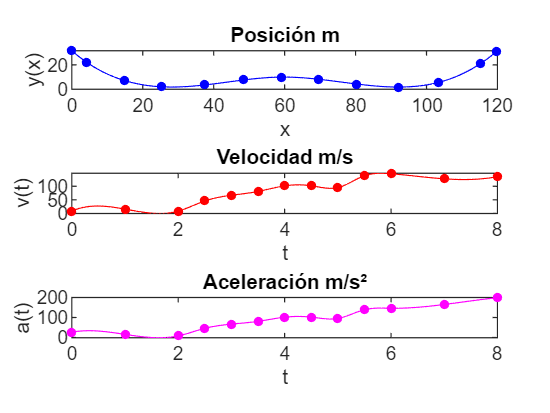



% Límites de los dibujos
l1_x = min(x); l2_x = max(x);
xx = linspace(l1_x, l2_x);
l1_t = min(t); l2_t = max(t);
tt = linspace(l1_t, l2_t);

% Dibujos
subplot(3, 1, 1)
plot(x, y,'b.', MarkerSize=12);
pp = spline(x, y);
yy = ppval(pp, xx);
hold on
plot(xx, yy, 'b-')
title('Posición m')
xlabel('x'); ylabel('y(x)')
hold off

subplot(3, 1, 2)
plot(t, v, 'r.', MarkerSize=12)
pp = spline(t, v);
yy = ppval(pp, tt);
hold on
plot(tt, yy, 'r-')
title('Velocidad m/s')
xlabel('t'); ylabel('v(t)')
hold off

subplot(3, 1, 3)
plot(t, a, 'm.', MarkerSize=12)
pp = spline(t, a);
yy = ppval(pp, tt);
hold on
plot(tt, yy, 'm-')
title('Aceleración m/s²')
xlabel('t'); ylabel('a(t)')
hold off